7.6 Flow Across Banks of Tubes 

Fundamentals of Heat and Mass Transfer, 8th Edition

Table for C and M values

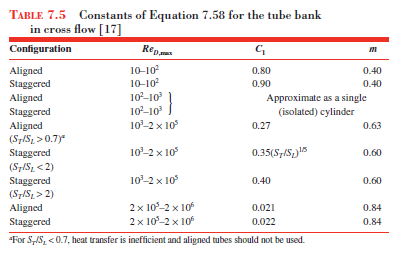

Table for C and M coeffiecents. 

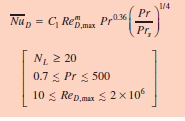

At least 20 tubes(**5 not 20 need correction factor**)

Prandlt number range, Reynolds number range

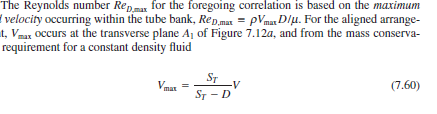

%Reynolds Number Calcs
BattColumns = 23;
BatteryRows =7;
Velo =6;
tempLow = 15+ 273.15;
battTemp = 70+ 273.15;
tempHigh = 43 + 273.15;
DiameterCells = 16.4/1000; % CHANGE THIS BECAUSE NO GAP


Funct

dynViscosity = py.CoolProp.CoolProp.PropsSI('V', 'T', tempLow, 'P|not_imposed', 101325, 'air');
densityAir = py.CoolProp.CoolProp.PropsSI('D', 'T', tempLow, 'P|not_imposed', 101325, 'air');
thermCond = py.CoolProp.CoolProp.PropsSI('L', 'T', tempLow, 'P|not_imposed', 101325, 'air');
ConstPNum = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air');
KinViscosity = dynViscosity/densityAir;


% Vert vs Horiz Spacing
St = 31.3/1000;% spacing between columns
Sl = 34.3/1000;%center spacing in direction of initial airflow
Vmax =  Velo*St/(St-DiameterCells);

ReynoldsNumber =  Vmax * DiameterCells / KinViscosity % WILL have to update C1 and M Manually before IF statements. 

ReynoldsNumber = 1.4104e+04

PrandtlAirLow = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempLow, 'P|not_imposed', 101325, 'air');
PrandtlAirHigh = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempHigh, 'P|not_imposed', 101325, 'air');

C1 = 0.35*(St/Sl)^(1/5);
mVal = 0.6; % Table
C2 = 0.95; %Table (correction factor for 5)



NusseltD = C2*C1*ReynoldsNumber^mVal*(PrandtlAirLow^0.36)*(PrandtlAirLow/PrandtlAirHigh)^(0.25);
Hline = NusseltD*thermCond/DiameterCells;

Adjusted Delta for warming


insideVarTop = (-pi*DiameterCells*(BattColumns*BatteryRows)*Hline);

insideVarBot = (densityAir*Velo*(BatteryRows)*St*ConstPNum);

adjDelTso = (battTemp - tempHigh)/(battTemp - tempLow) * exp(insideVarTop/insideVarBot);

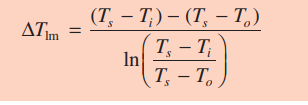

deltTlm = (battTemp-tempLow)-(adjDelTso)/(log((battTemp-tempLow)/(adjDelTso)));

qPrime = (BatteryRows*BattColumns)*(Hline*pi*DiameterCells*deltTlm);%in KW per m
qPrimeLadjust = qPrime*0.065;%Temp dissapated

qPrimeLadjust = 4.1073e+03

pressure loss

Pt = St/DiameterCells;
Pl = Sl/DiameterCells;
PTPL = Pt/Pl;
fancyX = 1.1;
fricFactor = 0.5;

deltPLoss = 5* fancyX * (densityAir/2*Vmax^2) * fricFactor;

deltPLoss = 267.7001

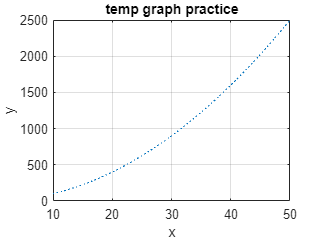

AirSpeed = 0:0.5:10;
y = AirSpeed.^3;
z = AirSpeed.^2;
hold on
yyaxis left
plot(y,AirSpeed,'.')
yyaxis right
plot(z,AirSpeed,'.')
xlabel('AirSpeed');
ylabel('HeatLoss And Ploss');
title('temp graph practice')
grid on;
hold off

function [HeatLoss,Ploss] = CoolingStats(AirSpeed)

All functions in a script must be closed with an 'end'.